I1 = imread("/Users/roshankandel/Downloads/CVAssignment/3/7/Left_Image_d1.jpg")

I1 = 480×640 uint8 matrix
   148   149   149   155   147   149   160   143   148   152   144   149   146   149   151   148   150   152   146   151   152   152   154   158   160   154   158   155   148   149   151   150   153   155   154   149   157   149   147   153   148   156   152   151   150   150   152   149   149   148
   147   146   147   156   150   147   151   151   144   154   142   146   154   149   145   154   150   154   155   154   149   155   144   154   156   158   157   153   153   153   150   153   150   153   149   150   153   152   151   159   150   153   151   150   152   150   153   152   149   147
   146   149   150   151   151   155   153   150   151   157   153   148   158   146   147   151   155   150   148   156   158   153   157   144   157   146   150   162   152   154   154   156   155   156   154   155   154   154   153   157   149   149   148   153   157   155   153   151   150   149
   153   150   148   148   150   149   152   151   147   154   155   15

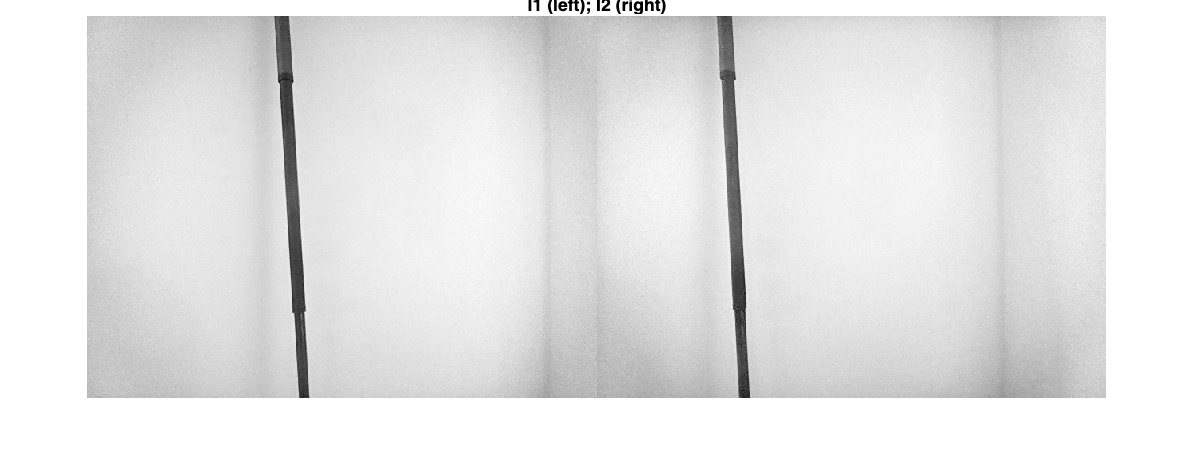

I2 = imread("/Users/roshankandel/Downloads/CVAssignment/3/7/Right_Image_d1.jpg");

% Convert to grayscale.
I1gray = im2gray(I1);
I2gray = im2gray(I2);
figure
imshowpair(I1,I2,"montage")
title("I1 (left); I2 (right)")

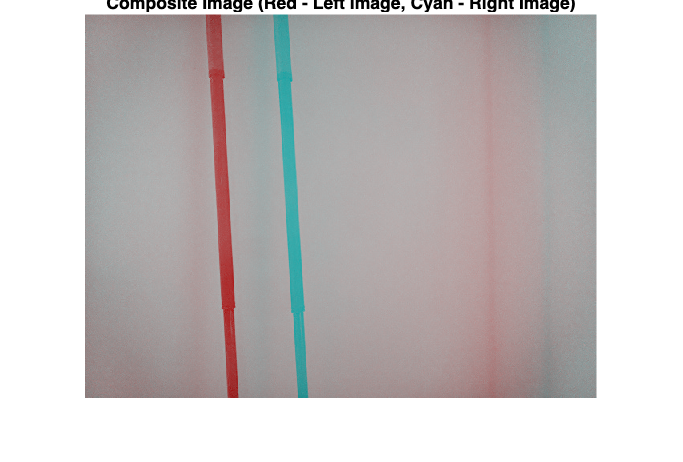








figure 
imshow(stereoAnaglyph(I1,I2))
title("Composite Image (Red - Left Image, Cyan - Right Image)")

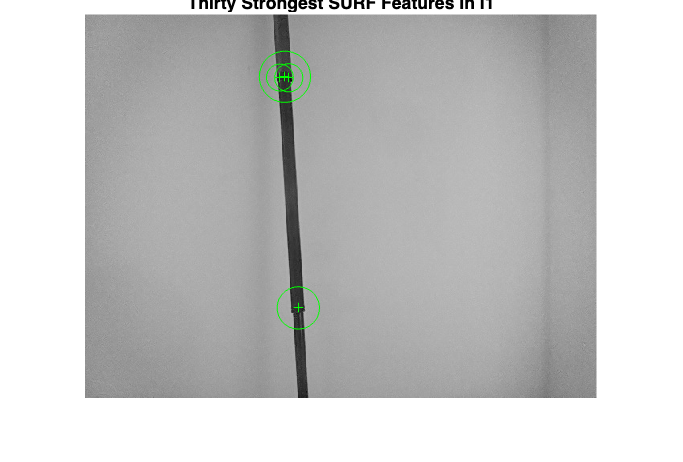



blobs1 = detectSURFFeatures(I1gray,MetricThreshold=2000);
blobs2 = detectSURFFeatures(I2gray,MetricThreshold=2000);
figure 
imshow(I1)
hold on
plot(selectStrongest(blobs1,30))
title("Thirty Strongest SURF Features In I1")

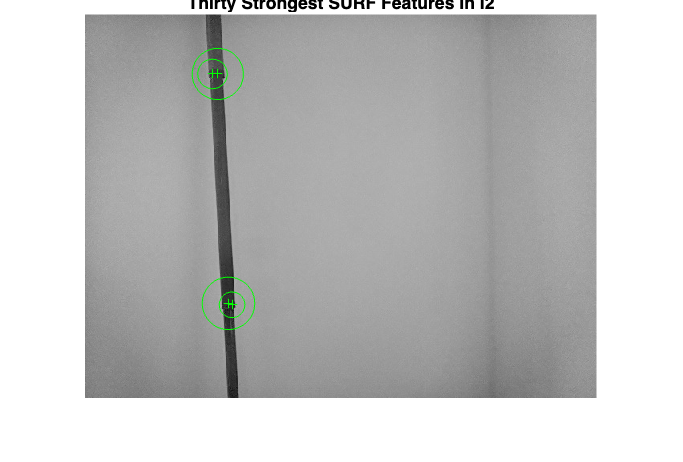



figure
imshow(I2)
hold on
plot(selectStrongest(blobs2,30))
title("Thirty Strongest SURF Features In I2")

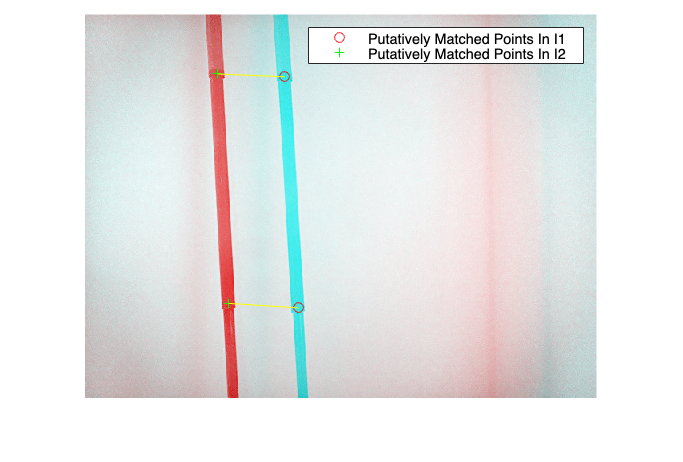


[features1,validBlobs1] = extractFeatures(I1gray,blobs1);
[features2,validBlobs2] = extractFeatures(I2gray,blobs2);
indexPairs = matchFeatures(features1,features2,Metric="SAD", ...
  MatchThreshold=5);
matchedPoints1 = validBlobs1(indexPairs(:,1),:);
matchedPoints2 = validBlobs2(indexPairs(:,2),:);
figure 
showMatchedFeatures(I1, I2, matchedPoints1, matchedPoints2)
legend("Putatively Matched Points In I1","Putatively Matched Points In I2")

[fMatrix, epipolarInliers, status] = estimateFundamentalMatrix(...
  matchedPoints1,matchedPoints2,Method="RANSAC", ...
  NumTrials=10000,DistanceThreshold=0.1,Confidence=99.99);

Error using estimateFundamentalMatrix>checkRuntimeStatus
matchedPoints1 and matchedPoints2 do not have enough points. The number of points in each set must be at least 8.

Error in estimateFundamentalMatrix (line 219)
  checkRuntimeStatus(statusCode, status);

  
if status ~= 0 || isEpipoleInImage(fMatrix,size(I1)) ...
  || isEpipoleInImage(fMatrix',size(I2))
  error(["Not enough matching points were found or "...
         "the epipoles are inside the images. Inspect "...
         "and improve the quality of detected features ",...
         "and images."]);
end

inlierPoints1 = matchedPoints1(epipolarInliers, :);
inlierPoints2 = matchedPoints2(epipolarInliers, :);

figure
showMatchedFeatures(I1, I2, inlierPoints1, inlierPoints2)
legend("Inlier Points In I1","Inlier Points In I2")
 [tform1, tform2] = estimateStereoRectification(fMatrix, ...
  inlierPoints1.Location,inlierPoints2.Location,size(I2));

 [I1Rect, I2Rect] = rectifyStereoImages(I1,I2,tform1,tform2);
figure
imshow(stereoAnaglyph(I1Rect,I2Rect))
title("Rectified Stereo Images (Red - Left Image, Cyan - Right Image)")
